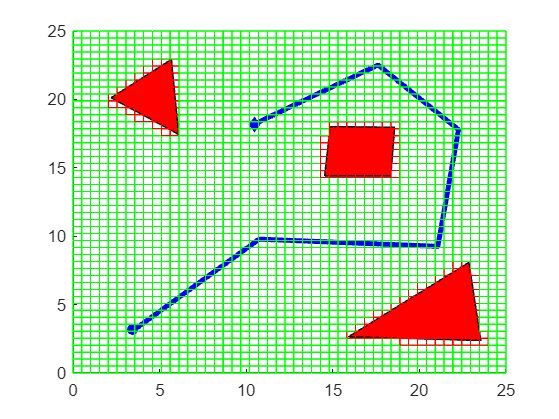

clear;
load("obstacles_1.mat");
load("path_obst.mat");
ROOM_WIDTH = 25;
ROOM_HEIGHT = 25;
RESOLUTION = 0.5;  % rozdzielczość
NO_RECT_H = ceil(ROOM_HEIGHT / RESOLUTION);
NO_RECT_W = ceil(ROOM_WIDTH / RESOLUTION);

grid_matrix_2d = zeros(NO_RECT_H, NO_RECT_W, 2);

for i = 1 : NO_RECT_H
    grid_matrix_2d(i, :, 1) = linspace(0, ROOM_WIDTH, NO_RECT_W);
end

for i = 1 : NO_RECT_W
    grid_matrix_2d(:, i, 2) = linspace(0, ROOM_HEIGHT, NO_RECT_H);
end

% Przeszkody
figure; hold on;
for i = 1 : length(obstacles)
    obst = obstacles{i};
    patch(obst(:, 1), obst(:, 2), "red")
end

% Wyrysowanie ścieżki
plot(path_obst(1, 2), path_obst(2, 3), 'bo', "MarkerFaceColor", "b")
plot(path_obst(:, 2), path_obst(:, 3), 'b', "LineWidth", 3);
plot(path_obst(end, 2), path_obst(end, 3), 'bdiamond', "MarkerFaceColor", "b")

% siatka zajętości
occupancy_grid = zeros(NO_RECT_W, NO_RECT_H);

% Sprawdzanie pól siatki - czy zawierają przeszkodę
for i = 1 : length(obstacles)
    obstacle = obstacles{i};
    %in = inpolygon(grid_matrix_2d(:,:,1), grid_matrix_2d(:,:,2), obstacle(:, 2));
    
    for j = 1 : NO_RECT_H
        for k = 1 : NO_RECT_W
            frame_vertices = [grid_matrix_2d(j, k, 1), grid_matrix_2d(j, k, 2);
                              grid_matrix_2d(j, k, 1) + RESOLUTION, grid_matrix_2d(j, k, 2);
                              grid_matrix_2d(j, k, 1), grid_matrix_2d(j, k, 2) + RESOLUTION;
                              grid_matrix_2d(j, k, 1) + RESOLUTION, grid_matrix_2d(j, k, 2) + RESOLUTION];
            
            frame = polyshape(frame_vertices);
            polyout = intersect(frame, polyshape(obstacle));
            %in_obst = inpolygon(frame_vertices(:,1), frame_vertices(:,2), obstacle(:,1), obstacle(:, 2));
            
            if polyout.NumRegions
                occupancy_grid(j, k) = 1;
            end
        end
    end

end

for i = 1 : NO_RECT_H
    for j = 1 : NO_RECT_W
        if occupancy_grid(i,j)
            rectangle("Position", [grid_matrix_2d(i, j, 1), grid_matrix_2d(i, j, 2), RESOLUTION, RESOLUTION], ...
                "EdgeColor", "red")
        else
            rectangle("Position", [grid_matrix_2d(i, j, 1), grid_matrix_2d(i, j, 2), RESOLUTION, RESOLUTION], ...
                "EdgeColor", "green")
        end
    end
end
axis([0 ROOM_WIDTH 0 ROOM_HEIGHT]);

hold off;